# Sensing System - Performance Evaluation

## Initialize the Evaluation Script

clear;
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
% file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
 file_path = "4GHz.json";

config_path = david_path + file_path;

### Generate a test set parameters for evaluating performance

%specify maximum constraints
valid_slopes = [1,100];
valid_chirp_periods = [15,100];
valid_BWs_MHz = [30,3500];
num_adc_samples = 128;
num_cases = 200;

simulator = Simulator_revB();
            
simulator.load_params_from_JSON(config_path);

[slopes,chirp_periods,adc_sampling_rates] = ...
    characterization_functions.initialize_sensing_subsystem_test_cases_general(num_cases, ...
                valid_slopes, ...
                valid_chirp_periods, ...
                valid_BWs_MHz, ...
                num_adc_samples);

configurations_passed = characterization_functions.check_test_configurations(slopes, ...
    chirp_periods, ...
    adc_sampling_rates, ...
    num_adc_samples, ...
    config_path);

All Configurations passed 


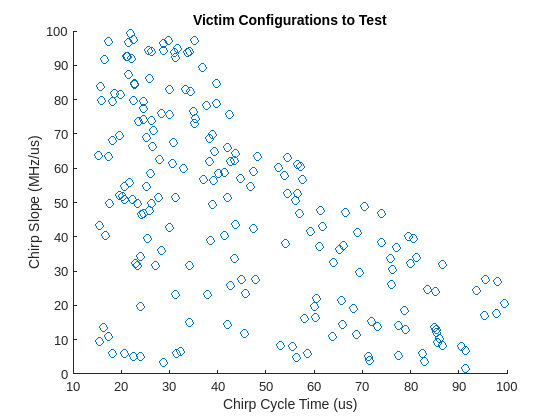

characterization_functions.plot_test_configurations(slopes,chirp_periods);

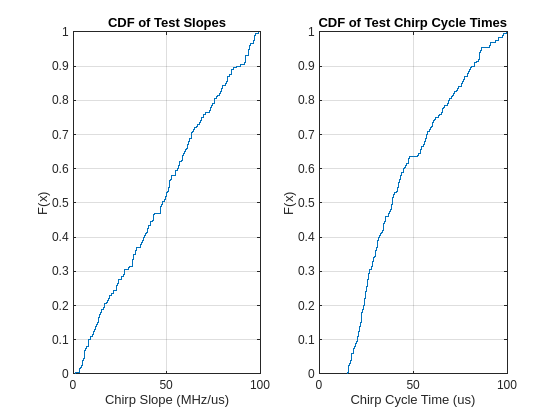

characterization_functions.plot_test_configuration_cdfs(slopes,chirp_periods);

### Run all of the test configurations and save results to a file

frames_to_compute = 7;

testing_data = characterization_functions.run_sensing_performance_test_cases( ...
                num_cases, ...
                frames_to_compute, ...
                slopes, ...
                chirp_periods, ...
                adc_sampling_rates, ...
                num_adc_samples, ...
                config_path, ...
                "sensing_subsystem_test_data.csv"); 

### Plot testing results

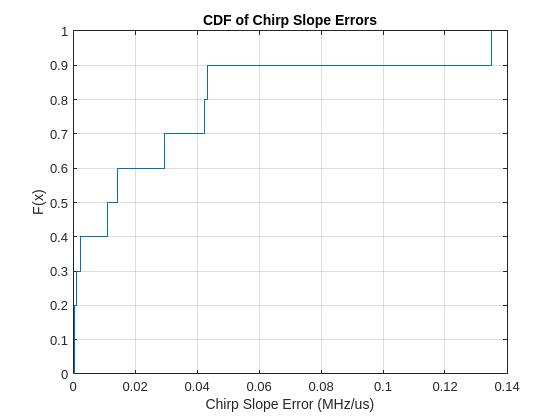

summary_table = 1×4 table
    Mean (MHz/us)    Variance (MHz/us)^2    MSE (MHz/us)^2    95th Percentile (MHz/us)
    _____________    ___________________    ______________    ________________________

      0.027977            0.0016918           0.0023053               0.13486         


%plot the cdf of the chirp slope errors
read_file_path = "sensing_subsystem_test_data.csv";
summary_table = characterization_functions.generate_slope_estimation_summary(read_file_path)

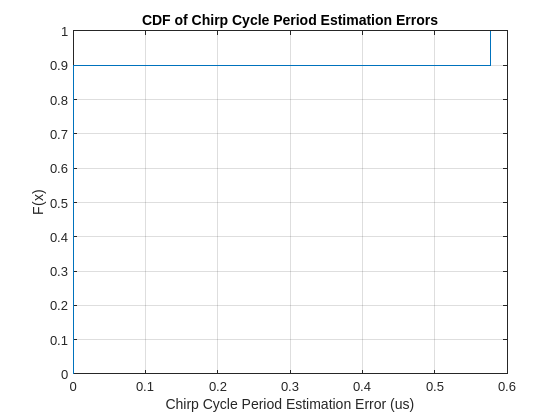

summary_table = 1×4 table
    Mean (us)    Variance (us)^2    MSE (us)^2    95th Percentile (us)
    _________    _______________    __________    ____________________

    0.057764         0.03329         0.033297           0.57704       


summary_table = characterization_functions.generate_chirp_period_estimation_summary(read_file_path)

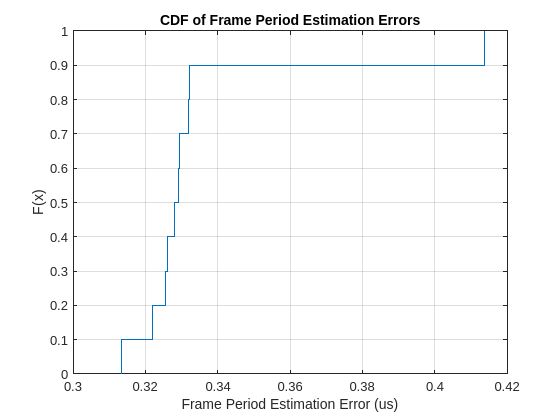

summary_table = 1×4 table
    Mean (us)    Variance (us)^2    MSE (us)^2    95th Percentile (us)
    _________    _______________    __________    ____________________

     0.33518       0.00079354        0.11306            0.41383       


%summary_table = characterization_functions.generate_frame_period_estimation_summary(read_file_path)

## Evaluating Frame Estimation Error Accuracy